# Raw signal dimensionality

We searched for two basis sets for the fluorescent data from the lip and tongue.  Exploring the data, we found that the two data sets, measured with an excitation light of 415 nm, are approximately 2 (lip) or 3 (tongue) dimensional.  They could be a little higher. 

We tested the idea that the lip basis set is a subset of the tongue, which is known to contain both porphyrin and chlorophyll that is not present on the lip.  Specifically, we asked if the tongue basis set could predict each of the basis functions in the lip.  The answer is no.  

We are now exploring whether we could make the two come together if we assume that there is a transmission function through the tissue that differs between tongue and lip.  That will take us on an expedition of fitting using a diagonal matrix (wave x wave) to relate the two sets of basis functions.  We will find a low dimensional parameterization of the diagonal matrix.

When done, we will test to see which fluorophores have emission functions, including perhaps some transmittance through blood with different amounts of oxygenation, that fall within the basis for the tongue and/or lip.

## Initialize the database and ISET

ieInit;

% Wavelength samples
waves = 500:700;

% Read in the database
[T,dataDir] = oeDatabaseCreate;

normalizationP = -1;   % Normalize for unit length, using oeReadFiles.

% SVD criterion for explained variance, if less than 1.
% criterion = 0.999;

% If criterion is more than 1, then we treat it as the number of
% dimensions.
criterion = 4;

% The difference (delta) in dimensions between the tongue, which is always
% equal (deltaDim = 0) or less than the number of dimensions for the lip.
deltaDim = 1;

## Tongue - excitations 

We tried various normalization approaches.  They are all the same.  

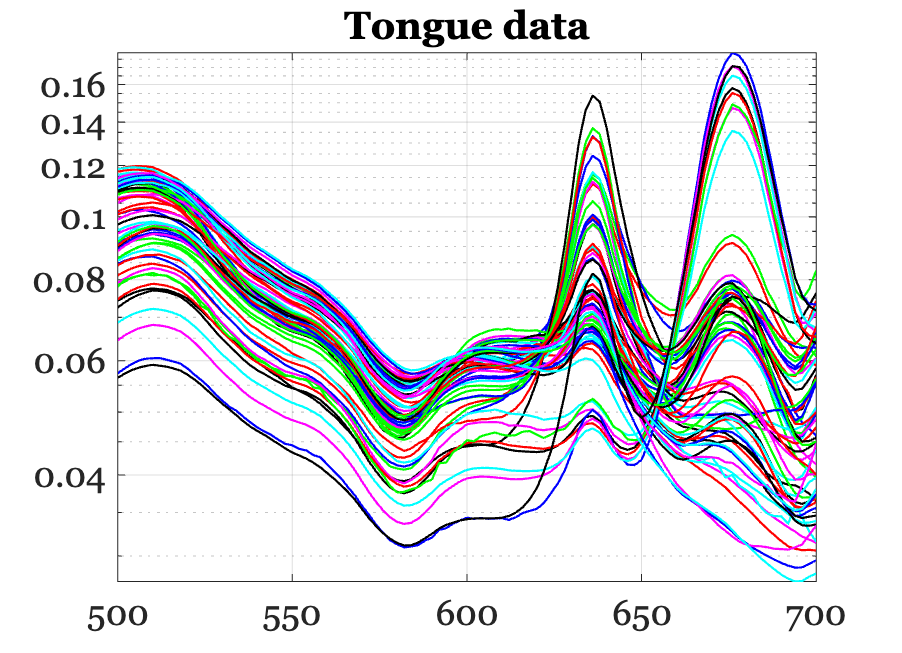

%{
filesAll = ieTableGet(T,...
     'substrate','tongue');
%}
% {
files405 = ieTableGet(T,...
    'ewave',405, ...
    'substrate','tongue');
files415 = ieTableGet(T,...
    'ewave',415, ...
    'substrate','tongue');
files450 = ieTableGet(T,...
    'ewave',450, ...
    'substrate','tongue');
filesAll = cat(1,files405,files415);
%}

dataTongue = oeReadFiles(filesAll,'waves',waves,'normalized wave',normalizationP);

ieFigure;
semilogy(waves,dataTongue);
grid on;
title('Tongue data');

## Find the dimensionality

Perform SVD explicitly, rather than using the pca() method.

[UT, S, ~] = svd(dataTongue, 'econ');

if criterion < 1
    eigenvalues = diag(S).^2;
    totalVariance = sum(eigenvalues);
    explainedVarianceRatio = eigenvalues / totalVariance;

    % Thresholding
    cumulativeVariance = cumsum(explainedVarianceRatio);
    dimensionality = find(cumulativeVariance >= criterion, 1, 'first');
else
    dimensionality = criterion;
end

fprintf('Tongue estimated dimensionality: %d\n', dimensionality);

Tongue estimated dimensionality: 4


## Show Tongue fluorescence basis vectors

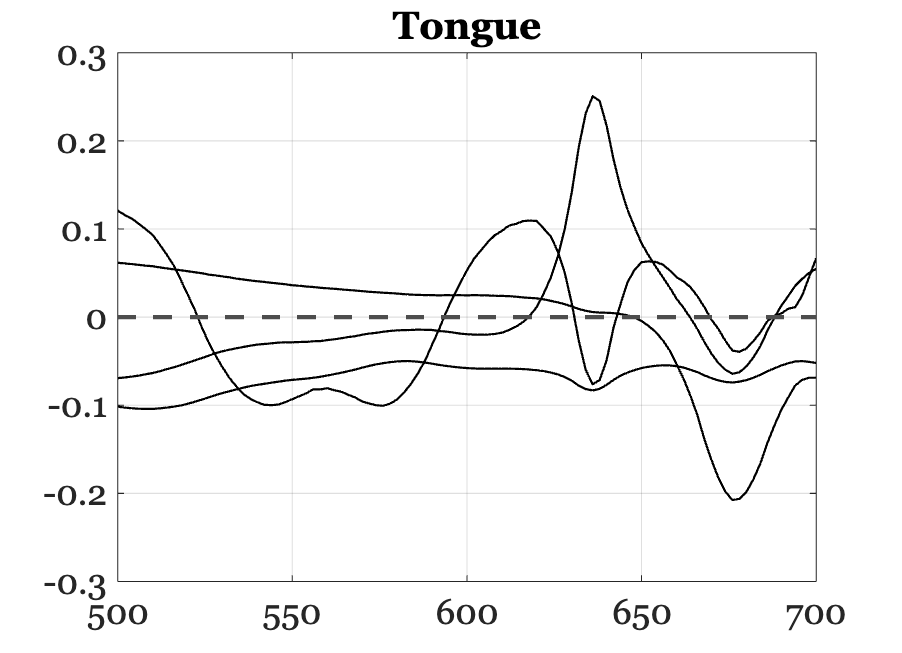

UT = UT(:,1:dimensionality);

% The mean and basis vectors
ieFigure;
plot(waves,UT,'k-');
grid on;
xaxisLine;
title('Tongue');

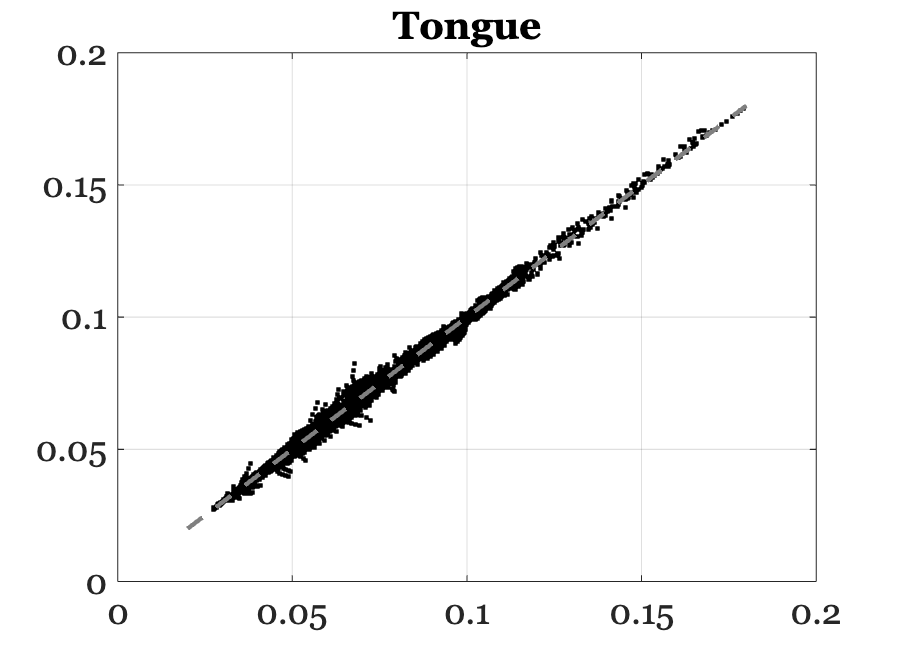


ieFigure;
wgts = UT'*dataTongue;
est = UT*wgts;
plot(est(:),dataTongue(:),'k.');
identityLine;
grid on;
title('Tongue');

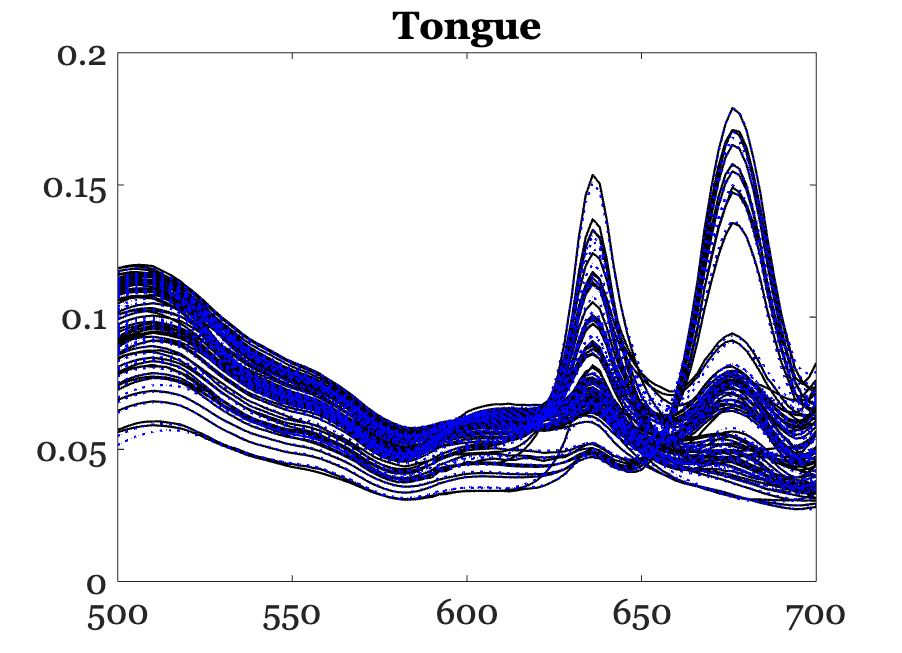


ieFigure;
plot(waves,dataTongue,'k-'); hold on;
plot(waves,est,'b:');
title('Tongue');

## Read the Lip data

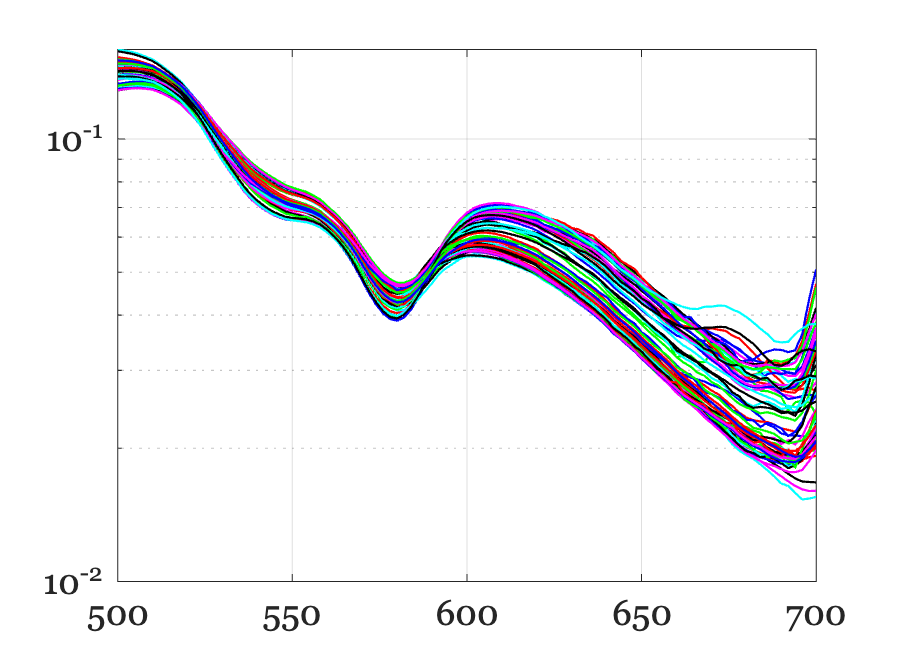

%{
filesAll = ieTableGet(T,...
    'substrate','lip');
%}
% {
files405 = ieTableGet(T,...
    'ewave',405, ...
    'substrate','lip');
files415 = ieTableGet(T,...
    'ewave',415, ...
    'substrate','lip');
files450 = ieTableGet(T,...
    'ewave',450, ...
    'substrate','lip');
filesAll = cat(1,files405,files415);
%}
dataLip = oeReadFiles(filesAll,'waves',waves,'normalized wave',normalizationP);

ieFigure;
semilogy(waves,dataLip); grid on;


[UL, S, ~] = svd(dataLip, 'econ');
if criterion < 1
    eigenvalues = diag(S).^2;
    totalVariance = sum(eigenvalues);
    explainedVarianceRatio = eigenvalues / totalVariance;

    % Thresholding
    cumulativeVariance = cumsum(explainedVarianceRatio);
    dimensionality = find(cumulativeVariance >= criterion, 1, 'first');
else
    % One less than tongue.  My choice.
    dimensionality = criterion;
    dimensionality = dimensionality - deltaDim;
end

fprintf('Estimated lip dimensionality: %d\n', dimensionality);

Estimated lip dimensionality: 3


## Compute bases with svd

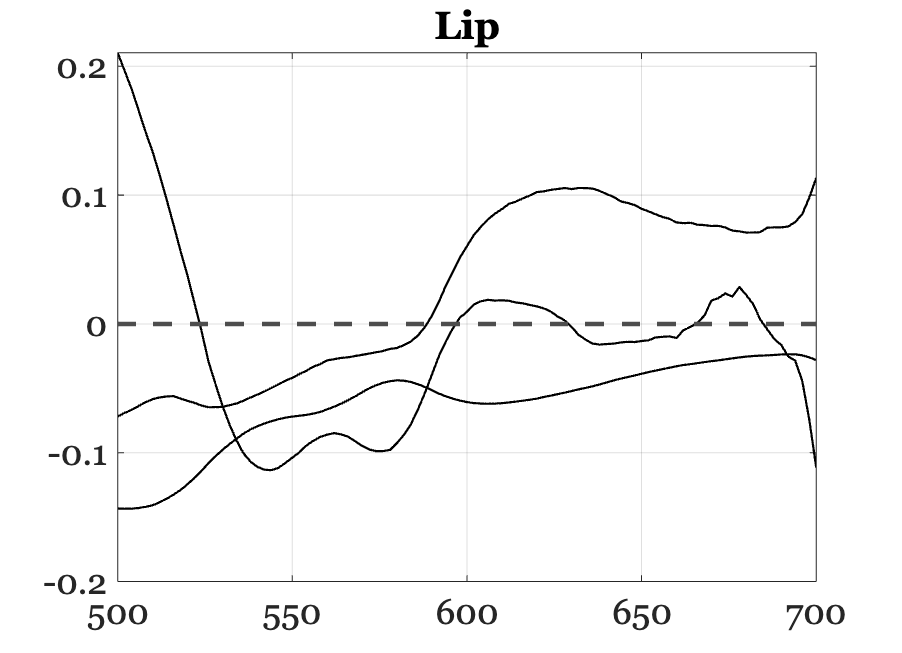

UL = UL(:,1:dimensionality);
ieFigure;
plot(waves,UL,'k-');
grid on;
xaxisLine;
title('Lip');

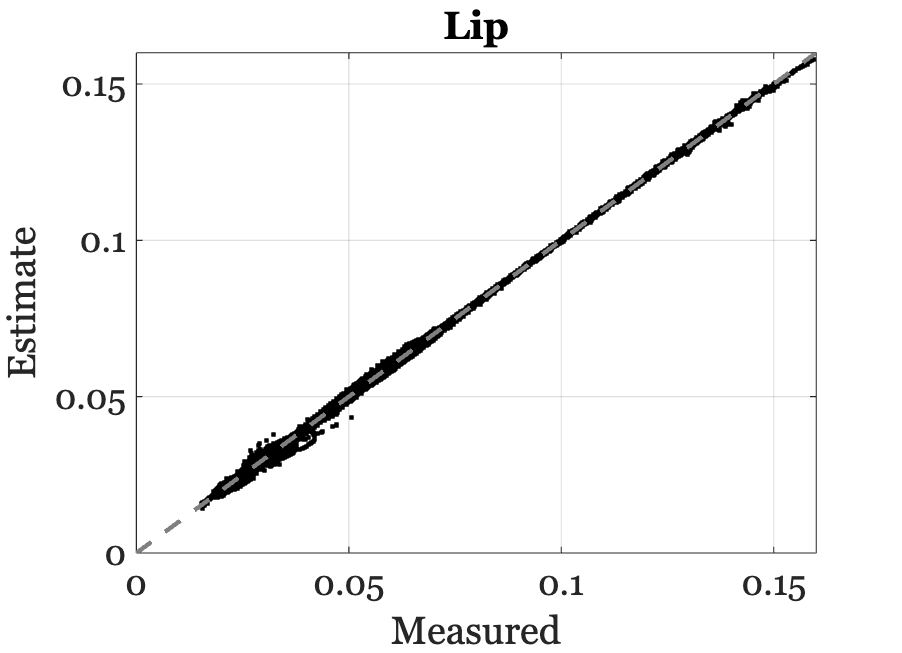


ieFigure;
wgts = UL'*dataLip;
est = UL*wgts;
plot(dataLip(:),est(:),'k.');
identityLine;
grid on; xlabel('Measured'); ylabel('Estimate');
title('Lip');

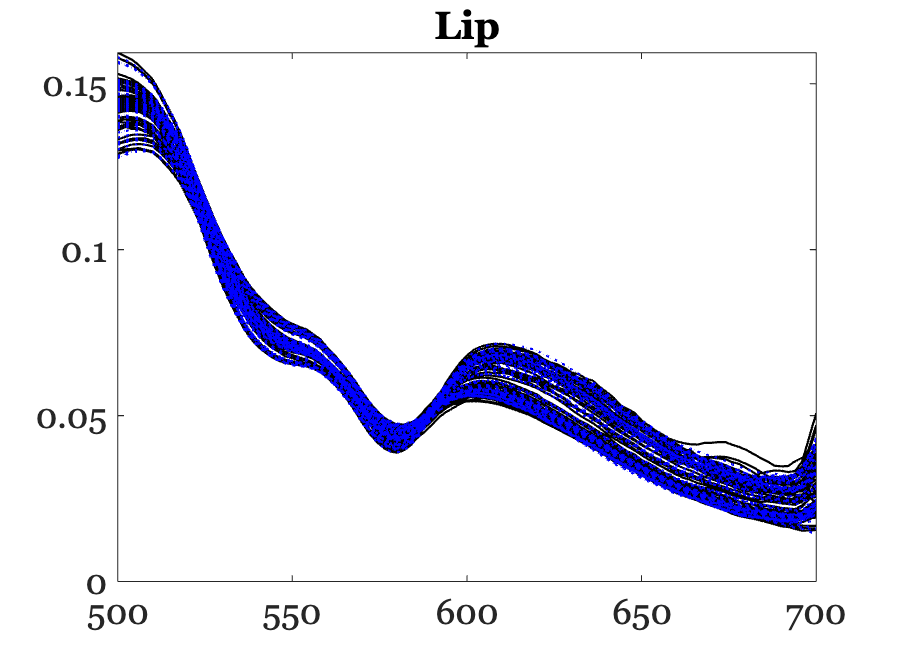


ieFigure;
plot(waves,dataLip,'k-'); hold on;
plot(waves,est,'b:');
title('Lip');

## Can we fit the Lip bases using the Tongue bases?

If we think that the tongue has the same fluorophores as the lip, except it also has porphyrin and chlorophyll, then we should be able to predict the lip data as weighted sums of the tongue data.  Or, equivalently, we should be able to predict the lip bases as weighted sums of the tongue bases.


$$U_L =U_T \;w$$


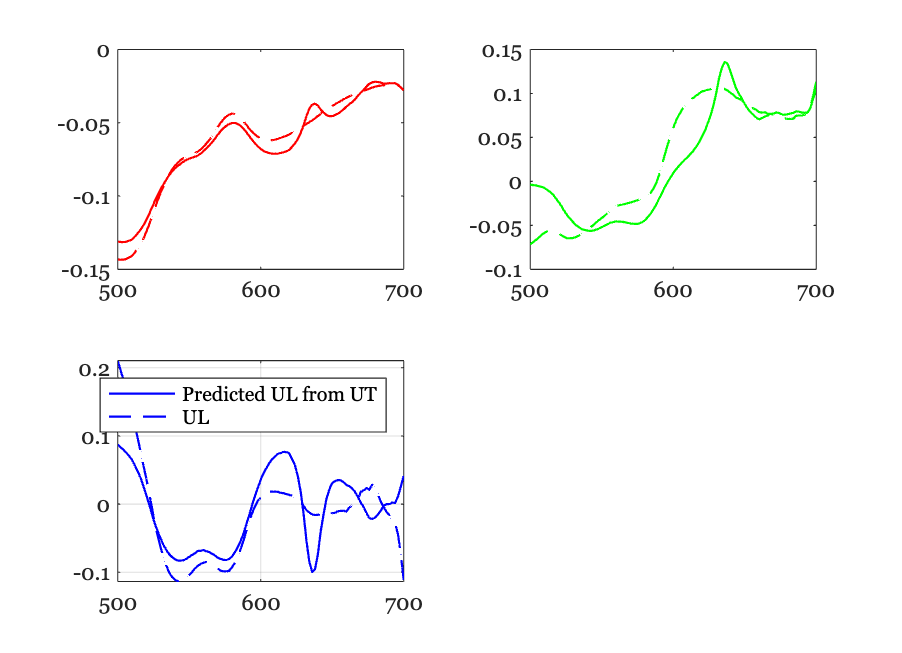

wgts = UT'*UL;
ULpred = UT*wgts;
sym1 = {'r-','g-','b-','k-','m-','c-'};
sym2 = {'r--','g--','b--','k--','m--','c--'};

ieFigure;
tiledlayout(2,2);
% 
for ii=1:size(UL,2)
    nexttile;
    hA = plot(waves,ULpred(:,ii),sym1{ii}); hold on;
    hB = plot(waves,UL(:,ii),sym2{ii}); hold on;
end

legend([hA,hB],{'Predicted UL from UT','UL'});
% xaxisLine;
grid on;

## Predict the lip data, $L_d$, from the tongue bases, $U_T$.  

This gives us a numerical sense of the miss compared to the noise in the measurements


$$L_d =U_T \;w$$


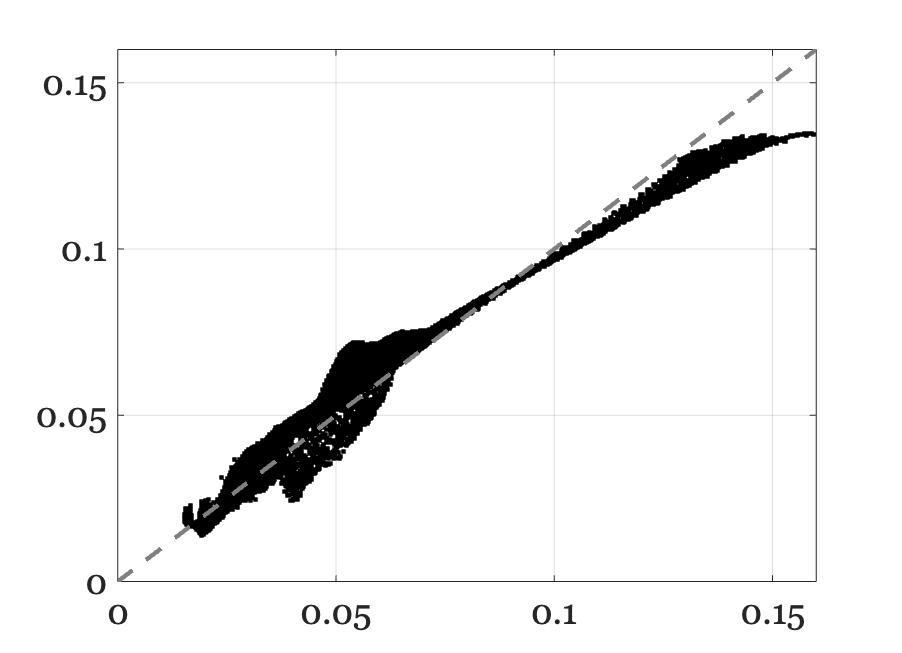

wgts = UT'*dataLip;
dataLipP = UT*wgts;

ieFigure;
plot(dataLip(:),dataLipP(:),'k.');
grid on;
identityLine;

## Is the problem tissue optics?

Suppose that there is a different wavelength filter in the tongue, $D_T$,  and lip, $D_L$.  Then we might have a pair of diagonal matrices that differ for the bases from the lip and tongue fluorophore signals.  We can combine the two diagonal matrices into one


$$D_{L\;} U_L =D_T U_T$$



$$U_L =D\;U_T$$


So a next project is to find a low-dimensional representation of the combined diagonal matrix, $D_\phi$, and search for its parameters, $\phi$ and the weights, $\omega$ that would satisfy


$$U_{L\;} =D_{\phi } U_T \omega$$


Here is a link to Gemini's solution in Matlab:  [https://g.co/gemini/share/1f70dfeefdde](https://g.co/gemini/share/1f70dfeefdde)

There is search code, written by ChatGPT, that we can check.  It takes oeSolveLipTongueCGPT() and returns the matrix and a diagonal.

% Do the fit
poly_degree = 15;
[wgts, D_diag] = oeSolveLipTongueCGPT(UL, UT, poly_degree);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0          29          71058.3                      4.03e+04
     1          58          6094.82    2.48296e-05       2.05e+04  
     2          87          13.0744              1           92.1  
     3         116          11.1099              1           86.6  
     4         145          4.73801              1           95.9  
     5         174          3.48562              1             68  
     6         203          3.01702              1           38.2  
     7         232          2.91941              1             21  
     8         261          2.86258              1           5.01  
     9         290          2.85461              1           1.58  
    10         348           2.8034             10           1.33  
    11         377          2.44881              1           1.28  
    12         551          2.40594        0.0797

disp(wgts)

    1.3977   -0.4454    0.1727
    0.0357   -0.5505    0.2883
    0.0447    1.2533   -0.2985
   -0.1763    0.3916    1.4835



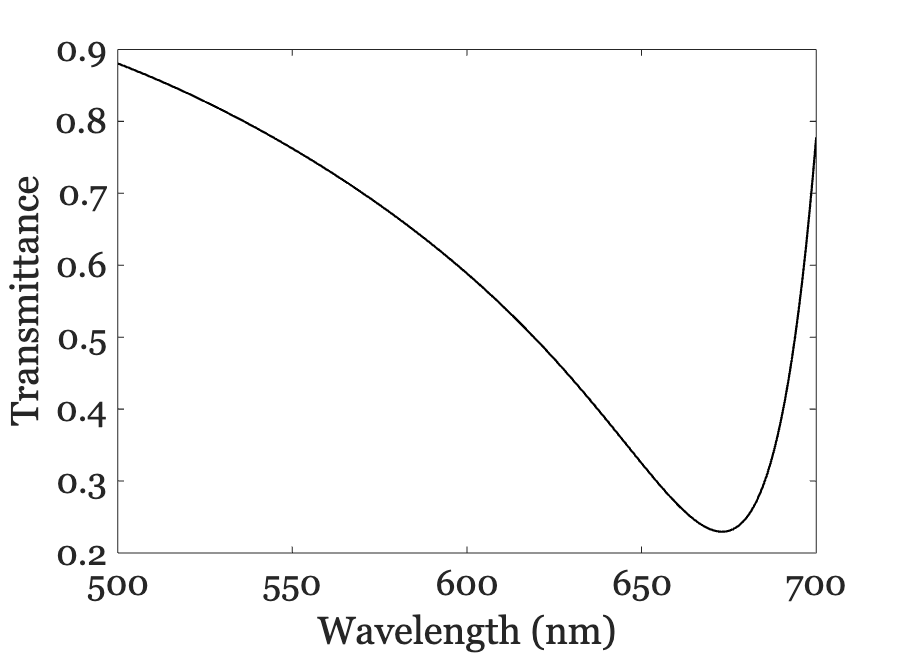


% Show the Diagonal transmittance term.
ieFigure; 
plot(waves,D_diag,'k-');
xlabel('Wavelength (nm)'); ylabel('Transmittance');

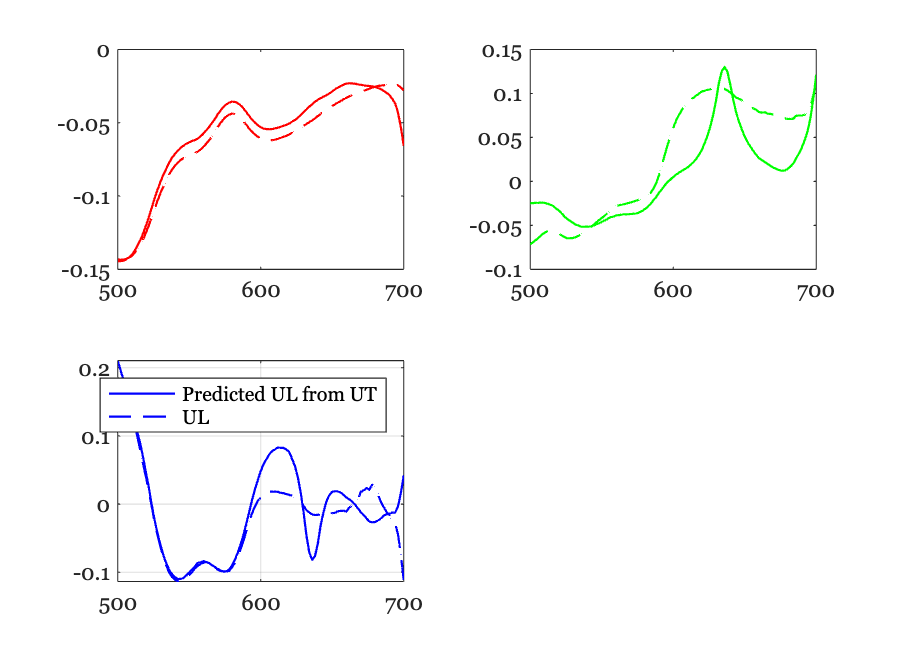

% Compare the predicted and actual lip basis functions
sym1 = {'r-','g-','b-','k-','m-','c-'};
sym2 = {'r--','g--','b--','k--','m--','c--'};
ULpred = diag(D_diag)*UT*wgts;

ieFigure;
tiledlayout(2,2);
% 
for ii=1:size(UL,2)
    nexttile;
    hA = plot(waves,ULpred(:,ii),sym1{ii}); hold on;
    hB = plot(waves,UL(:,ii),sym2{ii}); hold on;
end

legend([hA,hB],{'Predicted UL from UT','UL'});
% xaxisLine;
grid on;